Начальные данные

fd = 44100;
T = 8*10^(-3);
tau = 2.5*10^(-3);
A = 0.7;
t = 3;

Единичный график

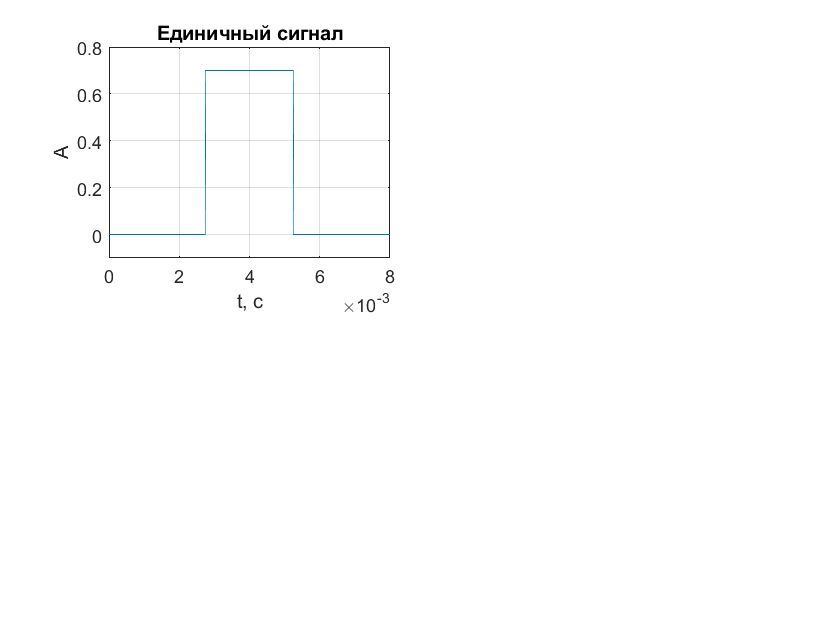

subplot(2,2,1)

tt_1 = linspace(0, T, T*fd);
y_1 = my_func_1(tt_1, T, A, tau);
plot(tt_1, y_1)
set(gcf, 'Visible', 'on')
xlabel('t, c')
ylabel('A')
ylim([-0.1 0.8])
grid on
title('Единичный сигнал')

Перидиодичный сигнал

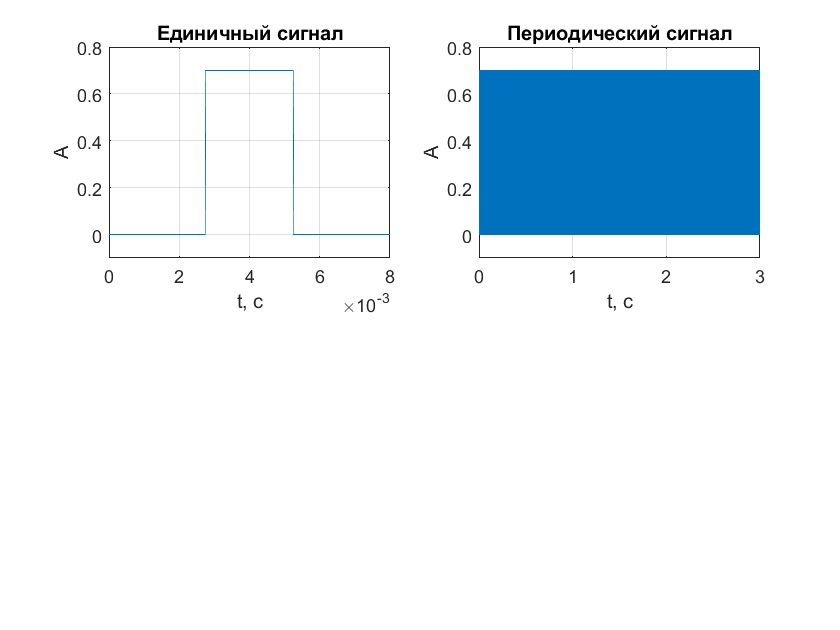

subplot(2,2,2)

tt_2 = linspace(0, t, t*fd);
y_2 = my_func_1(tt_2, T, A, tau);
plot(tt_2, y_2)
ylim([-0.1 0.8])
xlabel('t, c')
ylabel('A')
grid on
title('Периодический сигнал')

Единичный спектр

subplot(2,2,3)

L = length(tt_1)

L = 352

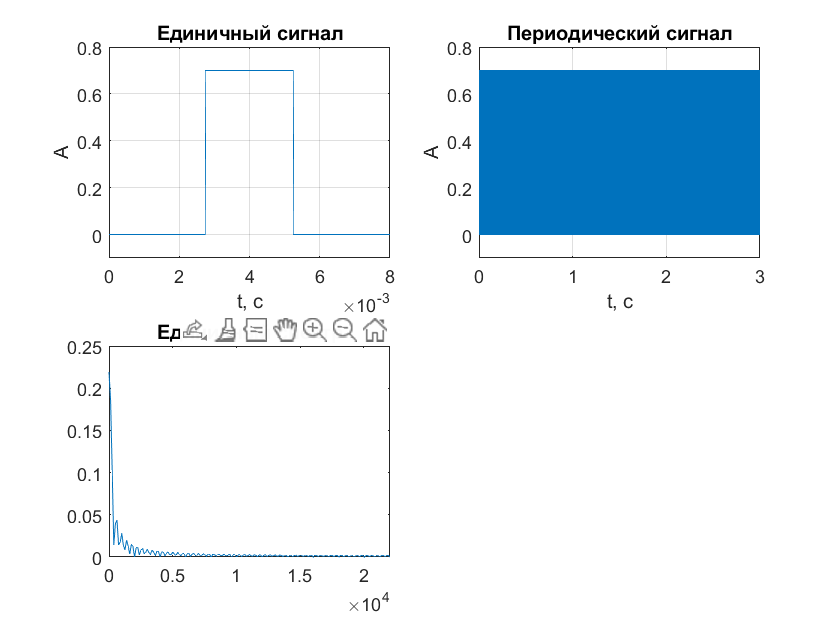

fft_signal_1 = fft(y_1);
P2 = abs(fft_signal_1/L);
P1 = P2(1:L/2 + 1);
f = fd * (0:(L/2))/L;
plot(f, P1)
title('Единичный спектр')

Пириодичный спектр

subplot(2,2,4)

L = length(tt_2)

L = 132300

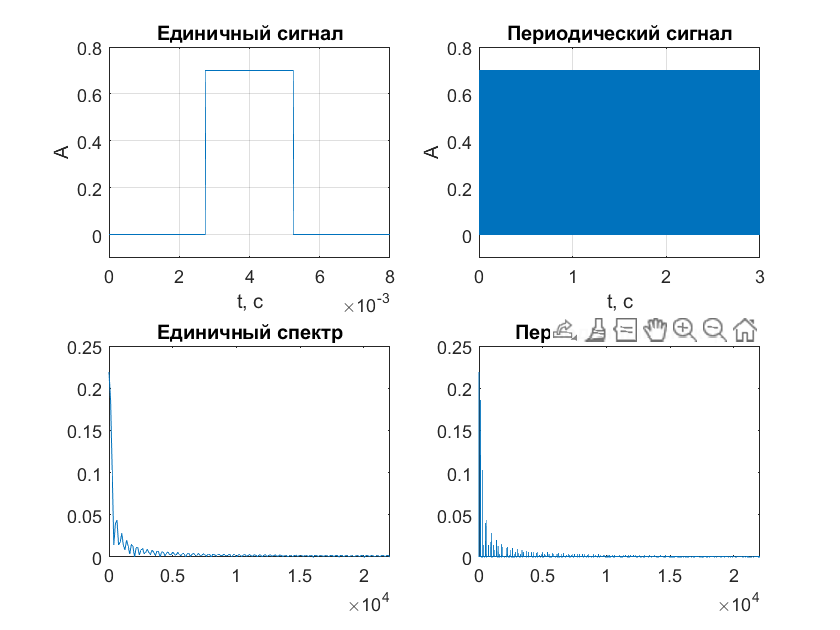

fft_signal_2 = fft(y_2);
P2 = abs(fft_signal_2/L);
P1 = P2(1:L/2 + 1);
f = fd * (0:(L/2))/L;
plot(f, P1)
title('Периодичный спектр')